clc;
clear;

Road_length  =1

Road_length = 1

car_number   = 10

car_number = 10

acceleration = 0.0029

acceleration = 0.0029

deceleration = -0.039

deceleration = -0.0390

%time limitis
time =130

time = 130

%limit speed
lim = 1

lim = 1

J = 1:car_number

J =      1     2     3     4     5     6     7     8     9    10


%A = rand(1,car_number).*Road_length
%x(J,1)= sort(A)
x(J,1) = (Road_length/car_number) *J

x =     0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000


v(J,1)=rand([1,car_number])

v =     0.9479
    0.0821
    0.1057
    0.1420
    0.1665
    0.6210
    0.5737
    0.0521
    0.9312
    0.7287


%minimum distance between cars
x0 = Road_length/(car_number*2)

x0 = 0.0500

num = car_number-1

num = 9

delT = 0.1

delT = 0.1000

k = time / delT

k = 1300

%
average(1) = 0

average = 0

t(1) = 0

t = 0

initialize road

for T=2:k
    for J=1:car_number
        if J == car_number
            dis(J,T) = x(1,T-1)-x(J,T-1);
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > x0
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration *delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        x(J,T)=x(J,T-1)+v(J,T)*delT;
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


x(J,T)=x(J,T)

x =     0.1000    0.1948    0.1948    0.1948    0.1948    0.1948    0.1948    0.1949    0.1949    0.1950    0.1951    0.1953    0.1954    0.1956    0.1959    0.1961    0.1964    0.1967    0.1971    0.1975    0.1979    0.1983    0.1988    0.1993    0.1998    0.2003    0.2009    0.2015    0.2022    0.2028    0.2035    0.2042    0.2050    0.2058    0.2066    0.2074    0.2083    0.2092    0.2101    0.2111    0.2121    0.2131    0.2141    0.2152    0.2163    0.2174    0.2186    0.2198    0.2210    0.2223
    0.2000    0.2082    0.2165    0.2248    0.2331    0.2415    0.2499    0.2583    0.2667    0.2752    0.2837    0.2922    0.3007    0.3093    0.3179    0.3266    0.3353    0.3440    0.3527    0.3614    0.3702    0.3790    0.3879    0.3968    0.4057    0.4146    0.4236    0.4326    0.4416    0.4506    0.4597    0.4688    0.4779    0.4871    0.4963    0.5055    0.5148    0.5241    0.5334    0.5427    0.5521    0.5521    0.5521    0.5521    0.5521    0.5521    0.5521    0.5521    0.5521    0

v(J,T)=v(J,T)

v =     0.9479    0.9482         0         0         0         0         0    0.0003    0.0006    0.0009    0.0012    0.0014    0.0017    0.0020    0.0023    0.0026    0.0029    0.0032    0.0035    0.0038    0.0041    0.0043    0.0046    0.0049    0.0052    0.0055    0.0058    0.0061    0.0064    0.0067    0.0070    0.0073    0.0075    0.0078    0.0081    0.0084    0.0087    0.0090    0.0093    0.0096    0.0099    0.0102    0.0104    0.0107    0.0110    0.0113    0.0116    0.0119    0.0122    0.0125
    0.0821    0.0824    0.0827    0.0829    0.0832    0.0835    0.0838    0.0841    0.0844    0.0847    0.0850    0.0853    0.0856    0.0858    0.0861    0.0864    0.0867    0.0870    0.0873    0.0876    0.0879    0.0882    0.0885    0.0887    0.0890    0.0893    0.0896    0.0899    0.0902    0.0905    0.0908    0.0911    0.0914    0.0916    0.0919    0.0922    0.0925    0.0928    0.0931    0.0934    0.0937         0         0         0         0         0         0         0         0     

average(T) = average(T)

average =          0    0.4354    0.2834    0.1485    0.1487    0.1489    0.1491    0.1493    0.1496    0.1498    0.1500    0.1503    0.1335    0.1337    0.0404    0.0406    0.0408    0.0410    0.0265    0.0267    0.0268    0.0270    0.0272    0.0273    0.0275    0.0277    0.0279    0.0280    0.0168    0.0170    0.0171    0.0173    0.0174    0.0176    0.0177    0.0179    0.0180    0.0182    0.0183    0.0185    0.0187    0.0095    0.0096    0.0098    0.0099    0.0101    0.0037    0.0038    0.0039    0.0040


k_1 = floor(k/3);
d_av = average(1,(k_1):k)

d_av =     0.0217    0.0219    0.0222    0.0224    0.0227    0.0230    0.0232    0.0235    0.0238    0.0240    0.0243    0.0245    0.0248    0.0196    0.0199    0.0202    0.0204    0.0207    0.0209    0.0212    0.0215    0.0217    0.0220    0.0222    0.0225    0.0228    0.0226    0.0224    0.0223    0.0222    0.0221    0.0165    0.0164    0.0166    0.0168    0.0171    0.0174    0.0176    0.0179    0.0182    0.0184    0.0187    0.0189    0.0192    0.0195    0.0197    0.0200    0.0202    0.0205    0.0208


av = mean(d_av)

av = 0.0216

Plot

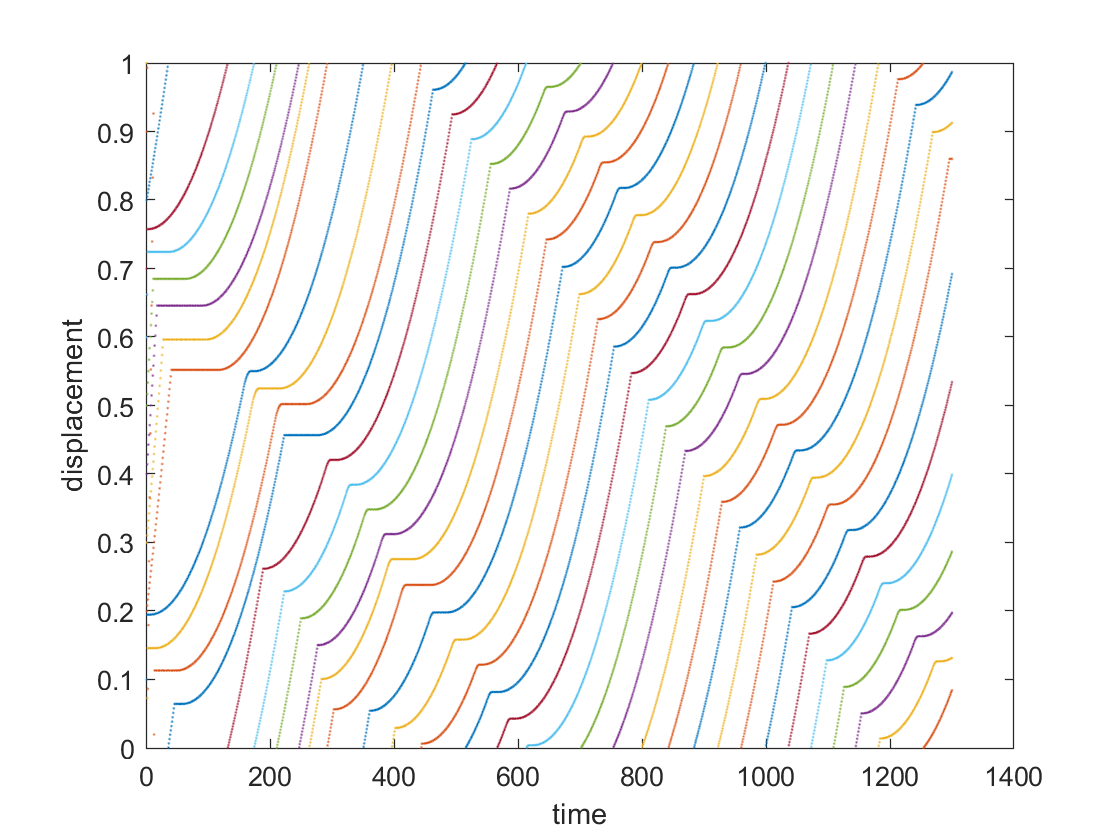

plot(x(1,:),".","MarkerSize",2);
hold on
for b = 2: car_number
    plot(x(b,:),".","MarkerSize",2)
end
xlabel('time')
ylabel('displacement')
hold off;

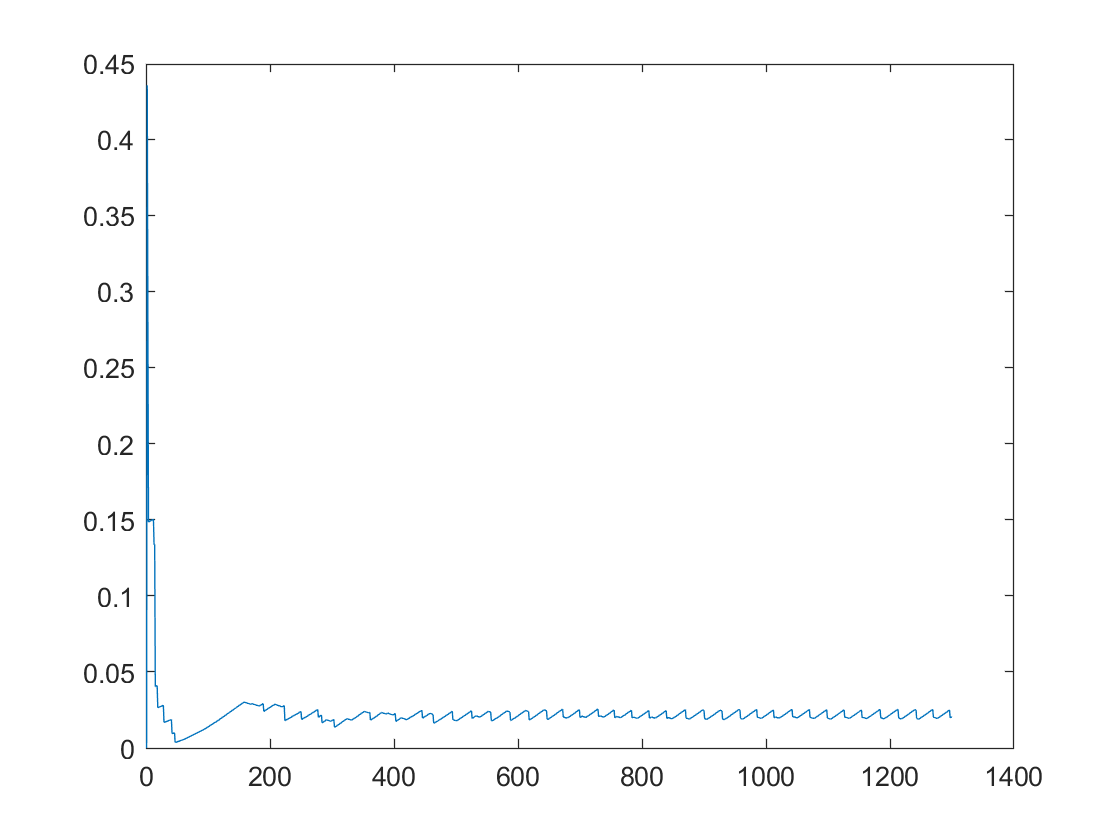

plot(average)